For lecture 7,

Part I: Parameterisation

clear;  close all;    

% We first Define 'para' structure as a container for parameters
para = struct();

% ---------------------------------------------
% |        1         |  2  |        3         |
% |     Anode        | Sep.|     Cathode      |]]
% |                  |     |                  |
% ---------------------------------------------

%% Constants 
    para.R  = 8.314;      % Gas constant [J/(mol·K)]
    para.F  = 96487;      % Faraday constant [C/mol]
    para.T_ref = 25 + 273.15;  % Reference temperature [K]

    % Cell nominal capacity [A·h]
    para.C_nom = 4.2;

    % Current collector resistance [Ω·m^2]
    para.Rc = 20e-4; 
    
%% Battery geometry
    para.thick1 = 73.50e-6;  % anode thickness [m]
    para.thick2 = 25.00e-6;  % separator thickness [m]
    para.thick3 = 70.00e-6;  % cathode thickness [m]
    para.L = para.thick1 + para.thick2 + para.thick3;  % total cell thickness [m]
    para.As = 0.0982;  % electrode active surface area [m^2]

%% Electrolyte
    para.ce_avg = 1000; %electrolyte average concentrations [mol/m^3]

%% Active porous material
    % Radii of solid particles
    para.Rs1 = 12.5e-6;  % anode particle radius [m]
    para.Rs3 = 8.5e-6;   % cathode particle radius [m]

    % Volume fractions of active material
    para.eps1s = 0.5052;  % anode
    para.eps3s = 0.5500;  % cathode

    % Specific interfacial surface area in porous electrodes [m^2/m^3]
    para.as1 = (3*para.eps1s)/para.Rs1;  % anode
    para.as3 = (3*para.eps3s)/para.Rs3;  % cathode

    % Max solid-phase concentrations [mol/m^3]
    para.cs1_max = 30556;  
    para.cs3_max = 51555;

    % Stoichiometry bounds determined by electrode balancing and ageing
    c_age = 1;
    % Stoichiometry bounds determined by electrode balancing and ageing
    para.soc0_a = 0.0068+c_age*0.01; % anode stoichiometry at 0% SOC
    para.soc1_a = 0.7560-c_age*0.01; % anode stoichiometry at 100% SOC
    para.soc0_c = 0.8933+c_age*0.01; % cathode stoichiometry at 0% SOC
    para.soc1_c = 0.4650-c_age*0.01; % cathode stoichiometry at 100% SOC

    % Diffusion coefficients (reference at 25 degree) [m^2/s]
    para.Ds1_ref = 3.9e-14;  
    para.Ds3_ref = 1.0e-14;
    
    % Reaction rate constants (reference at 25 degree) [m^(2.5)·mol^(-0.5)·s^(-1)]
    para.k1_ref = 1.764e-11;
    para.k3_ref = 6.667e-11;

    % OCP polynomials (Graphite & LiCoO2)
    % We'll store them as function handles that take stoichiometry x or y.
    para.U_ocp_anode = @(theta) ( ...
        0.7222 + 0.1387*theta + 0.0290*sqrt(theta) - 0.0172./theta + ...
        0.0019./(theta.^(1.5)) + 0.2808.*exp(0.90 - 15*theta) - ...
        0.7984.*exp(0.4465*theta - 0.4108) );
    
    para.U_ocp_cathode = @(theta) ( ...
       (-4.656 + 88.669*theta.^2 - 401.119*theta.^4 + 342.909*theta.^6 ...
        - 462.471*theta.^8 + 433.434*theta.^10) ./ ...
       (-1 + 18.933*theta.^2 - 79.532*theta.^4 + 37.311*theta.^6 ...
        - 73.083*theta.^8 + 95.96*theta.^10) );

Task 1

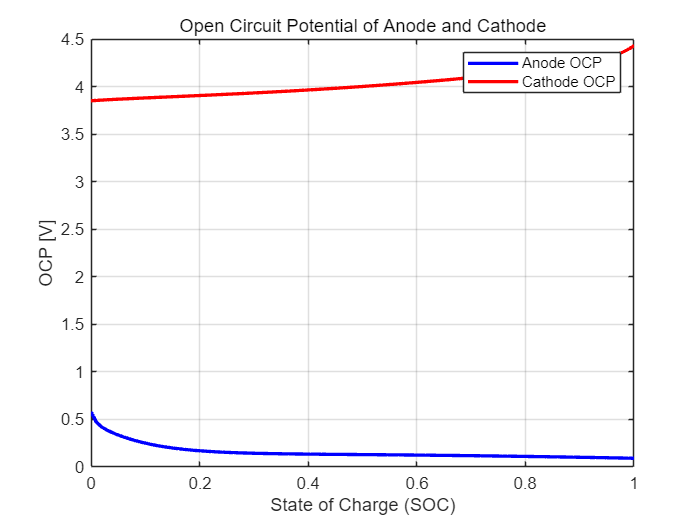

%% Plot OCP curves for anode and cathode
SOC = linspace(0, 1, 100);

% Map SOC to stoichiometry
stoich_anode = para.soc0_a + SOC * (para.soc1_a - para.soc0_a);
stoich_cathode = para.soc0_c + SOC * (para.soc1_c - para.soc0_c);

% Compute OCP for anode and cathode
U_anode = para.U_ocp_anode(stoich_anode);
U_cathode = para.U_ocp_cathode(stoich_cathode);

% Compute Open Circuit Voltage (OCV) within stoichiometry limits
OCV = U_cathode - U_anode;

% Plot OCP curves for anode and cathode
figure;
plot(SOC, U_anode, 'b', 'LineWidth', 2); hold on;
plot(SOC, U_cathode, 'r', 'LineWidth', 2);
legend('Anode OCP', 'Cathode OCP');
xlabel('State of Charge (SOC)'); ylabel('OCP [V]');
title('Open Circuit Potential of Anode and Cathode');
grid on;

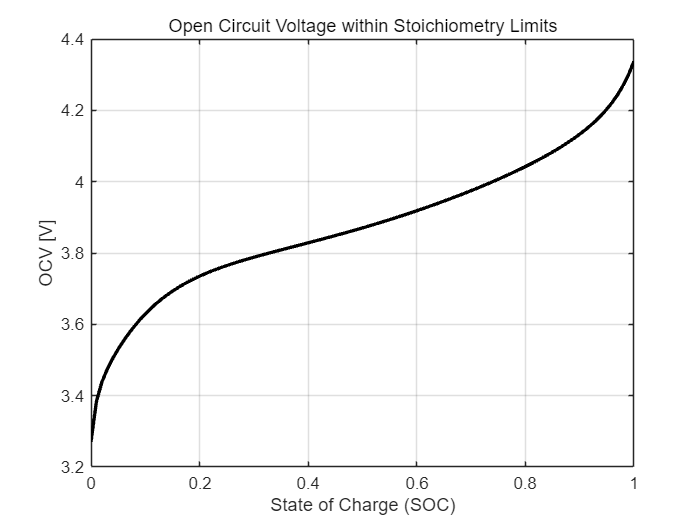

% Plot OCV within stoichiometry limits
figure;
plot(SOC, OCV, 'k', 'LineWidth', 2);
xlabel('State of Charge (SOC)'); ylabel('OCV [V]');
title('Open Circuit Voltage within Stoichiometry Limits');
grid on;

Task 1 Questions

- **Physical Meaning of Stoichiometry Limits**

Stoichiometry limits refer to the allowable range of lithium occupancy in the electrode materials. For the anode (e.g., graphite), the lower limit (e.g., soc0ₐ) indicates a nearly depleted state of lithium, while the upper limit (e.g., soc1ₐ) represents the fully lithiated state. For the cathode (e.g., LiCoO₂), the corresponding limits (soc0_c and soc1_c) define the bounds of lithium concentration.These limits essentially define the safe and effective operating window for the electrode reactions.

- **How Stoichiometry Limits Constrain Cell Voltage Performance**

The open-circuit voltage (OCV) of a battery is the difference between the equilibrium potentials of the cathode and the anode, both of which are functions of their respective stoichiometries. When a cutoff, such as 0.8, is set for one of the electrodes, it corresponds to a specific potential that defines the voltage limit during charging or discharging. Therefore, the cell’s voltage is bounded by the potentials at these stoichiometric limits. Exceeding these limits can lead to irreversible reactions or structural damage to the electrode materials, compromising battery safety and longevity.

- **Impact of Changes in Stoichiometry Limits During Aging**

As the battery ages, degradation of the electrode materials (due to side reactions, structural changes, or loss of active material) can lead to shifts in the stoichiometry limits:

**Narrowing of the Usable Range:** The effective range for lithium intercalation and deintercalation becomes smaller, meaning fewer lithium ions participate in the reversible reactions.

**Alteration of the Voltage Platform:** Since the electrode equilibrium potentials depend on stoichiometry, a shift in these limits will change the OCV profile of the battery.

**Performance Decline:** The reduced stoichiometry range directly leads to lower capacity and potential instability in the voltage profile during charge/discharge cycles, ultimately degrading overall battery performance and lifespan.

Part II: Radial discreatisation for spherical diffusion

function dcdt = diffusion_sphere(c, R, D_ref, N)
    % c: vector of length N+1
    % R: particle radius
    % D_ref: diffusion coefficient
    % N: # of sub-intervals in radial discretization
    
    dr = R / N;
    r  = linspace(0, R, N+1)';
    
    dcdt = zeros(size(c));
    
    % Interior nodes
    for i = 2:N
        dcdt(i) = D_ref * ( ...
            (c(i+1) - 2*c(i) + c(i-1)) / dr^2 + ...
            (2/r(i)) * (c(i+1) - c(i-1)) / (2*dr) );
    end
    
    % Boundary at r=0 (due to symmetry)
    dcdt(1) = 2 * D_ref * ...
    (c(2) - c(1)) / dr^2;  % or a specialized second-order approach
end


Part III: Numerical time integration

function dcdt = spm_ode_system(~, x, para)
    % Unpack states
    Nn = para.Nr_anode;
    Np = para.Nr_cathode;
    
    c_n = x(1:Nn+1);                       % anode concentration profile
    c_p = x(Nn+2 : Nn+1 + (Np+1));         % cathode concentration profile
    
    % Initialise dxdt
    dcdt = zeros(size(x));
    
    % Compute diffusion in anode
    dc_n = diffusion_sphere(c_n, para.Rs1, para.Ds1_ref, Nn);
    
    % Compute diffusion in cathode
    dc_p = diffusion_sphere(c_p, para.Rs3, para.Ds3_ref, Np);
    
    % Flux boundary condition from the applied current
    
    % Negative sign for anode if current is extraction of Li
    flux_n = para.I_app / para.F / para.thick1;  % [mol/(m^2·s)]
    flux_p = -para.I_app / para.F / para.thick3;  % same magnitude, but direction is different
    
    % Apply boundary condition at the outer radius:
    dc_n(end) = dc_n(end) - flux_n;  % anode
    dc_p(end) = dc_p(end) - flux_p;  % cathode
    
    % Combine
    dcdt(1:Nn+1) = dc_n;
    dcdt(Nn+2 : Nn+1+(Np+1)) = dc_p;
end

Part IV: Constant charge/discharge simulations

Crate = -1;                              % e.g., 1C = current rate that allows full discharge in 1 hour
I_app = Crate * para.C_nom / para.As;    % applied density [A/m^2];             
para.I_app = -I_app;                     % store in para
para.time_span = [0, 3600];              % 1-hour if 1C
para.T = 273 + 25;                       % room temperature

% uniform Li concentration in anode/cathode
% by convention, I_app > 0 is charging and < 0 discharging
    if I_app >= 0
        c_n0 = para.soc0_a * para.cs1_max;  % anode
        c_p0 = para.soc0_c * para.cs3_max;  % cathode
    else
        c_n0 = para.soc1_a * para.cs1_max;  
        c_p0 = para.soc1_c * para.cs3_max; 
    end

    para.Nr_anode = 30; %number of discreatisation points
    para.Nr_cathode = 30;
    x0 = [ repmat(c_n0, para.Nr_anode+1, 1); ...
           repmat(c_p0, para.Nr_cathode+1, 1) ];

opts = odeset('RelTol',1e-6, 'AbsTol',1e-8);
[t_sol, x_sol] = ode15s(@(t,x) spm_ode_system(t, x, para), para.time_span, x0, opts);

% extract the ion concentrations in solid
% Do you want how to find the surface concentration?
c_n_all = x_sol(:, 1:para.Nr_anode+1);
c_p_all = x_sol(:, para.Nr_anode+2 : para.Nr_anode+1 + (para.Nr_cathode+1));

V_cell = zeros(size(t_sol));
for k = 1:length(t_sol)
    V_cell(k) = compute_terminal_voltage(x_sol(k,:)', para);
end

Task 2: 

function V_cell = compute_terminal_voltage(x, para)
    % Unpack size parameters for the discretized SPM (if applicable)
    Nn = para.Nr_anode;    % Number of radial nodes in the anode
    Np = para.Nr_cathode;  % Number of radial nodes in the cathode
   
    % ---------------------------------------------------------------------
    % 1. Extract surface concentrations from the state vector
    %    Here we assume:
    %    - x(Nn+1)     = surface concentration at the anode
    %    - x(Nn+1+Np+1) = surface concentration at the cathode
    % ---------------------------------------------------------------------
    c_n_surf = x(Nn+1);           
    c_p_surf = x(Nn+1 + Np+1);    

    % ---------------------------------------------------------------------
    % 2. Compute surface stoichiometries (dimensionless)
    % ---------------------------------------------------------------------
    x1 = c_n_surf / para.cs1_max;   % anode stoichiometry
    y3 = c_p_surf / para.cs3_max;   % cathode stoichiometry

    % ---------------------------------------------------------------------
    % 3. Compute OCPs at anode and cathode
    % ---------------------------------------------------------------------
    U_n = para.U_ocp_anode(x1);      % anode OCP [V]
    U_p = para.U_ocp_cathode(y3);    % cathode OCP [V]

    % ---------------------------------------------------------------------
    % 4. Ohmic drop through internal/contact resistance
    %    I = para.I_app (applied current, in A)
    %    Rc = para.Rc   (contact/internal resistance, in ohm·m^2)
    % ---------------------------------------------------------------------
    I       = para.I_app;           % current [A]
    IR_drop = I * para.Rc;          % ohmic drop [V]

    % ---------------------------------------------------------------------
    % 5. Overpotentials at anode and cathode (symmetric Butler-Volmer)
    %
    %    i_0 = k_ref * sqrt( c_surf * (c_s_max - c_surf) * c_e )
    %    i   = I / A  (current density [A/m^2])
    %
    %    eta = (2 * R * T / F) * asinh( i / (2 * i_0 ) )
    %
    %    Note: We assume alpha = 0.5 for symmetric BV.
    % ---------------------------------------------------------------------
   % Overpotentials (very simplified or zero for demonstration)
    i_0_n = para.k1_ref*para.F.*(para.ce_avg.^0.5).*(c_n_surf.^0.5).*(para.cs1_max-c_n_surf).^0.5;  % at anode
    i_0_p = para.k3_ref*para.F.*(para.ce_avg.^0.5).*(c_p_surf.^0.5).*(para.cs3_max-c_p_surf).^0.5;  % at cathode
    eta_n = (2*para.R*para.T/para.F).*asinh(-0.5*para.I_app/para.as1/para.thick1./i_0_n);
    eta_p = (2*para.R*para.T/para.F).*asinh( 0.5*para.I_app/para.as3/para.thick3./i_0_p);
    

    V_cell = U_p - U_n - IR_drop - eta_n - eta_p;
end

Plot

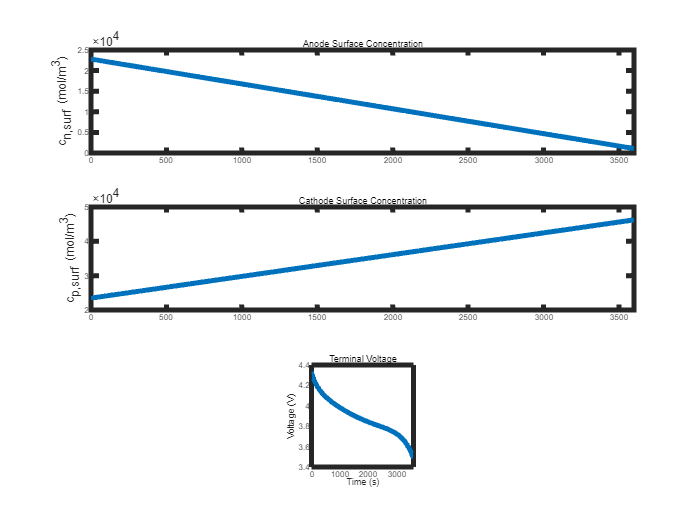

% Example plot
lw = 3; % line width for the curves

figure(); 
subplot(3,1,1);
plot(t_sol, c_n_all(:,end), 'LineWidth',lw);
ylabel('c_{n,surf} (mol/m^3)');
xlim([0 3600]);
title('Anode Surface Concentration');
set(gca, 'FontSize', 5, 'LineWidth', 3, 'Box', 'on');

subplot(3,1,2);
plot(t_sol, c_p_all(:,end), 'LineWidth',lw);
ylabel('c_{p,surf} (mol/m^3)');
xlim([0 3600]);
title('Cathode Surface Concentration');
set(gca, 'FontSize', 5, 'LineWidth', 3, 'Box', 'on');

subplot(3,1,3);
plot(t_sol, V_cell, 'LineWidth',lw);
xlabel('Time (s)'); ylabel('Voltage (V)');
title('Terminal Voltage');
axis square;
xlim([0 3600]);
set(gca, 'FontSize', 5, 'LineWidth', 3, 'Box', 'on');

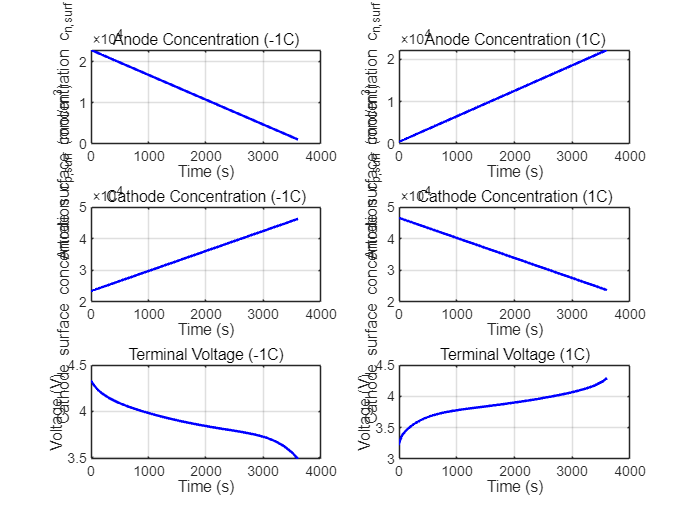

% Charge/discharge rates
Crates = [-1, 1];  % Discharge (-1C) & Charge (+1C)
lw = 1.5;  % Line width
color = 'b';  % Uniform color

% Set up figure (3 rows, 2 columns layout)
figure;

for j = 1:length(Crates)
    Crate = Crates(j);

    % Set the current
    I_app = Crate * para.C_nom / para.As;   
    para.I_app = -I_app;
    para.time_span = [0, 3600 / abs(Crate)];  % 1C = 1 hour, 2C = 0.5 hour

    % Set initial SOC
    if I_app >= 0  % Charging
        c_n0 = para.soc0_a * para.cs1_max;  % Anode
        c_p0 = para.soc0_c * para.cs3_max;  % Cathode
    else  % Discharging
        c_n0 = para.soc1_a * para.cs1_max;  
        c_p0 = para.soc1_c * para.cs3_max;  
    end

    para.Nr_anode = 30;
    para.Nr_cathode = 30;
    x0 = [ repmat(c_n0, para.Nr_anode+1, 1); ...
           repmat(c_p0, para.Nr_cathode+1, 1) ];

    % Solve ODE
    opts = odeset('RelTol',1e-6, 'AbsTol',1e-8);
    [t_sol, x_sol] = ode15s(@(t,x) spm_ode_system(t, x, para), para.time_span, x0, opts);

    % Calculate terminal voltage
    V_cell = arrayfun(@(k) compute_terminal_voltage(x_sol(k,:)', para), 1:length(t_sol));

    % Extract concentration data
    c_n_all = x_sol(:, 1:para.Nr_anode+1);
    c_p_all = x_sol(:, para.Nr_anode+2 : para.Nr_anode+1 + (para.Nr_cathode+1));

    % Determine subplot position
    col = j;  % Column 1 for discharge, Column 2 for charge
    
    subplot(3,2,1 + (col-1));  % Anode surface concentration
    plot(t_sol, c_n_all(:,end), color, 'LineWidth', lw);
    xlabel('Time (s)'); ylabel('Anode surface concentration c_{n,surf} (mol/m^3)');
    title(['Anode Concentration (' num2str(Crate) 'C)']);
    grid on;

    subplot(3,2,3 + (col-1));  % Cathode surface concentration
    plot(t_sol, c_p_all(:,end), color, 'LineWidth', lw);
    xlabel('Time (s)'); ylabel('Cathode surface concentration c_{p,surf} (mol/m^3)');
    title(['Cathode Concentration (' num2str(Crate) 'C)']);
    grid on;

    subplot(3,2,5 + (col-1));  % Terminal voltage
    plot(t_sol, V_cell, color, 'LineWidth', lw);
    xlabel('Time (s)'); ylabel('Voltage (V)');
    title(['Terminal Voltage (' num2str(Crate) 'C)']);
    grid on;
end

Set charging parameter,

% Set charging/discharging parameters (e.g., 1C charging)
Crate = 4;
I_app = Crate * para.C_nom / para.As; 
para.I_app = -I_app;  % During charging, current may be defined as negative (depending on model definition)
para.time_span = [0, 900];  % Simulate charging process over 1 hour

%%% Define segment
para.Nr_anode   = 30;
para.Nr_cathode = 30;

% Define uniform initial concentration (adjust as needed)
if I_app >= 0
    c_n0 = para.soc0_a * para.cs1_max;  % Anode
    c_p0 = para.soc0_c * para.cs3_max;  % Cathode
else
    c_n0 = para.soc1_a * para.cs1_max;
    c_p0 = para.soc1_c * para.cs3_max;
end
x0 = [ repmat(c_n0, para.Nr_anode+1, 1); repmat(c_p0, para.Nr_cathode+1, 1) ];

% Simulate charging/discharging using the current-driven SPM model
opts = odeset('RelTol',1e-6, 'AbsTol',1e-8);
[t_sol, x_sol] = ode15s(@(t,x) spm_ode_system(t,x,para), para.time_span, x0, opts);

% Extract the concentration profiles at the end of the charging/discharging process
c_n_end = x_sol(end, 1:para.Nr_anode+1);
c_p_end = x_sol(end, para.Nr_anode+2:end);
x0_relax = [c_n_end, c_p_end];  % Use as the initial state for the relaxation simulation

%% Phase 2: Relaxation Simulation (No current)
% Set the applied current to 0 to simulate concentration relaxation under zero current
para.I_app = 0;
% Optionally, reset the time span for the relaxation simulation, e.g., 1 hour
para.time_span = [0, 3600];

[t_relax, x_relax] = ode15s(@(t,x) spm_ode_system(t,x,para), para.time_span, x0_relax, opts);

% Extract the concentration data for the anode and cathode during relaxation
c_n_relax = x_relax(:, 1:para.Nr_anode+1);
c_p_relax = x_relax(:, para.Nr_anode+2:end);

% % Plot the surface concentration evolution during relaxation
% figure;
% subplot(2,1,1);
% plot(t_relax, c_n_relax(:,end), 'LineWidth',2);
% xlabel('Time (s)'); ylabel('Anode Surface Concentration (mol/m^3)');
% title('Anode Concentration Relaxation');
% 
% subplot(2,1,2);
% plot(t_relax, c_p_relax(:,end), 'LineWidth',2);
% xlabel('Time (s)'); ylabel('Cathode Surface Concentration (mol/m^3)');
% title('Cathode Concentration Relaxation');

% Define the radial grids for anode and cathode
r1 = linspace(0, para.Rs1, para.Nr_anode+1);
r3 = linspace(0, para.Rs3, para.Nr_cathode+1);

% Select the concentration at the end of the relaxation simulation
c_n_final = c_n_relax(end,:);   % All radial nodes of the anode at the last time step
c_p_final = c_p_relax(end,:);     % All radial nodes of the cathode at the last time step

% Calculate the average concentration
c_avg_n = (3 / para.Rs1^3) * trapz(r1, c_n_all(end,:) .* (r1.^2));
c_avg_p = (3 / para.Rs3^3) * trapz(r3, c_p_all(end,:) .* (r3.^2));

fprintf('Avg concentration at 1C: %.2f mol/m^3\n', c_avg_n);

Avg concentration at 1C: 20628.54 mol/m^3


fprintf('Avg concentration at 1C: %.2f mol/m^3\n', c_avg_p);

Avg concentration at 1C: 26811.26 mol/m^3


For lecture 8,

Part I: numerical method

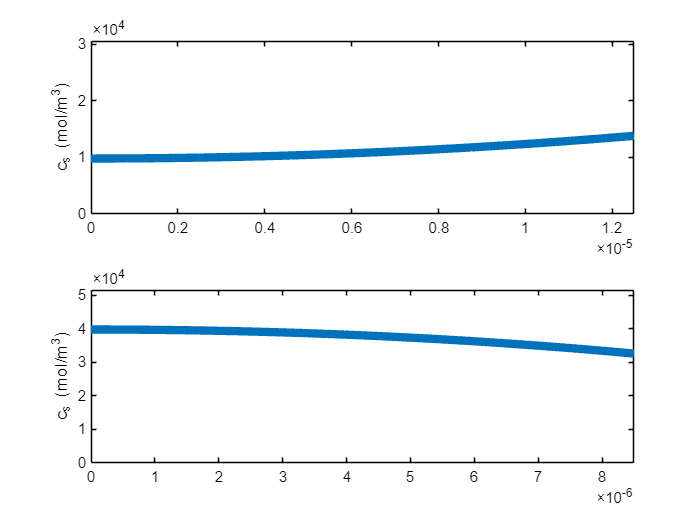

r1  = linspace(0, para.Rs1, para.Nr_anode+1);
    r3  = linspace(0, para.Rs3, para.Nr_cathode+1);
    for k = 1:2:length(t_sol)
        subplot(2,1,1);
        plot(r1, c_n_all(k,:), 'LineWidth', 5);
        ylabel('c_s (mol/m^3)');
        xlim([0 para.Rs1]);
        ylim([0 para.cs1_max]);
        set(gca, 'XColor', 'k', 'YColor', 'k');
        
        subplot(2,1,2);
        plot(r3, c_p_all(k,:), 'LineWidth', 5);
        ylabel('c_s (mol/m^3)');
        xlim([0 para.Rs3]);
        ylim([0 para.cs3_max]);
        set(gca, 'XColor', 'k', 'YColor', 'k');
        drawnow;
    end

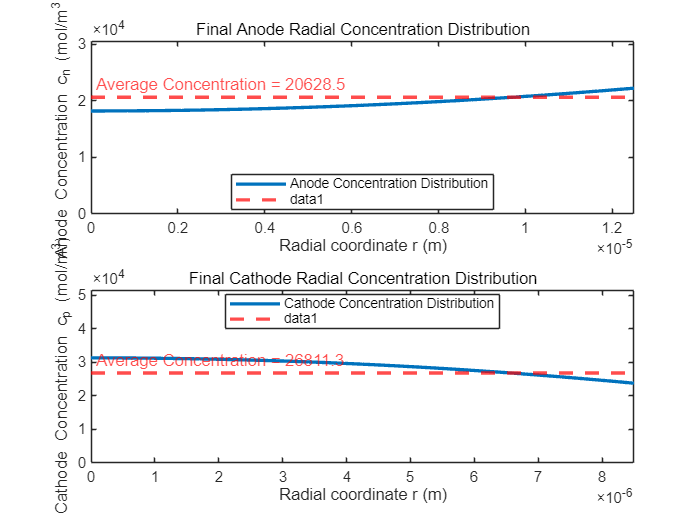

% Generate radial coordinates (assumed to be defined)
r1 = linspace(0, para.Rs1, para.Nr_anode+1);
r3 = linspace(0, para.Rs3, para.Nr_cathode+1);

% Assume that c_n_all and c_p_all store the anode and cathode concentration data for all time steps
% Here we take the data from the final time step
c_n_final = c_n_all(end,:);
c_p_final = c_p_all(end,:);

% Calculate the average concentration (already computed)
c_avg_n = (3 / para.Rs1^3) * trapz(r1, c_n_final .* (r1.^2));
c_avg_p = (3 / para.Rs3^3) * trapz(r3, c_p_final .* (r3.^2));

% Plot the final time step's radial concentration distribution and add a horizontal line for the average concentration
figure('Name', 'Final Time Step: Radial Concentration Distribution and Average Concentration');
% Plot for the anode
subplot(2,1,1);
plot(r1, c_n_final, 'LineWidth', 2, 'DisplayName', 'Anode Concentration Distribution');
hold on;
yline(c_avg_n, '--r', sprintf('Average Concentration = %.1f', c_avg_n), 'LineWidth', 2, 'LabelHorizontalAlignment', 'left');
hold off;
xlabel('Radial coordinate r (m)');
ylabel('Anode Concentration c_n (mol/m^3)');
xlim([0, para.Rs1]);
ylim([0, para.cs1_max]);
title('Final Anode Radial Concentration Distribution');
legend('Location', 'best');

% Plot for the cathode
subplot(2,1,2);
plot(r3, c_p_final, 'LineWidth', 2, 'DisplayName', 'Cathode Concentration Distribution');
hold on;
yline(c_avg_p, '--r', sprintf('Average Concentration = %.1f', c_avg_p), 'LineWidth', 2, 'LabelHorizontalAlignment', 'left');
hold off;
xlabel('Radial coordinate r (m)');
ylabel('Cathode Concentration c_p (mol/m^3)');
xlim([0, para.Rs3]);
ylim([0, para.cs3_max]);
title('Final Cathode Radial Concentration Distribution');
legend('Location', 'best');

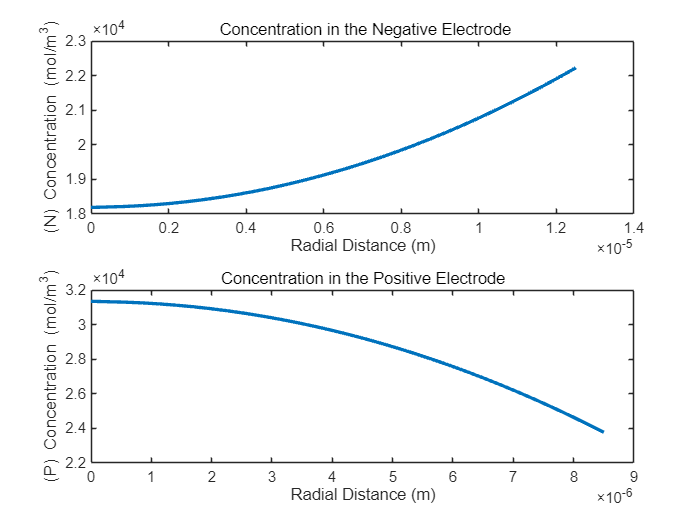

figure;
subplot(2,1,1);
plot(r1, c_n_final, 'LineWidth',2);
xlabel('Radial Distance (m)');
ylabel('(N) Concentration (mol/m^3)');
title(' Concentration in the Negative Electrode');

subplot(2,1,2);
plot(r3, c_p_final, 'LineWidth',2);
xlabel('Radial Distance (m)');
ylabel('(P) Concentration (mol/m^3)');
title('Concentration in the Positive Electrode');

% Task 3
para.Ea_Ds1 = 35e3;         % Activation energy for anode diffusion [J/mol]
para.Ea_Ds3 = 29e3;         % Activation energy for cathode diffusion [J/mol]

para.Ea_k1 = 20e3;          % Activation energy for anode reaction rate [J/mol]
para.Ea_k3 = 58e3;          % Activation energy for cathode reaction rate [J/mol]

% Define the fitting coefficients 
c1_num = [-16515.05308;38379.18127;-37147.89470;19329.75490;...
        -5812.27813;1004.91101;-91.79326;3.29927;0.00527];
c1_den = [165705.85970;-385821.16070;374577.31520;-195881.64880;...
        59431.30001;-10481.80419;1017.23480;-48.09287;1];
c3_num = [0; 0.61154; -1.36455; 0.92837; -0.19952];
c3_den = [3.04876; -9.82431; 11.47636; -5.66148; 1];

% Create dU/dT(theta) functions
dU1dT = @(x1) 1e-3 * (polyval(c1_num(1:7), x1) ./ polyval(c1_den(1:7), x1)); %anode
dU3dT = @(x3) 1e-3 * (polyval(c3_num, x3) ./ polyval(c3_den, x3));           %cathode


para.Cp     = 750;                  % Heat capacity [J/kg/K]
para.rho    = 1626;                 % Density [kg/m3]

para.height =   65e-3;            	% 18650 height [m]
para.diam   =   18e-3;           	% 18650 diameter [m]

% Surface area to volume ratio for an 18650 cell [m-1]
para.SA_V   =   4*(1 + para.diam/para.height/2)/para.diam;
% Volume of the cell
para.Vc     =   pi*(para.diam/2)^2*para.height;

% Convective boundary condition
para.h      =   30;         % Convection heat transfer coefficient [W/m2/K]                  
para.T_amb  = 25 + 273.15;  % Ambient temperature [K]

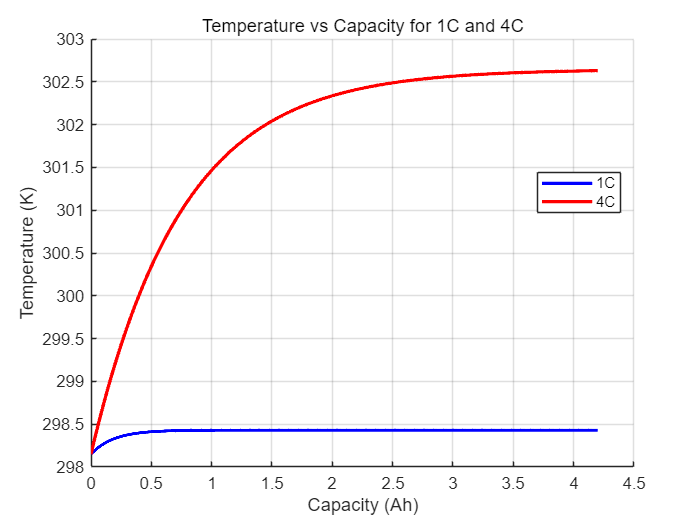

% Task 3: Plot Temperature vs Capacity for 1C and 4C

% Define simulation time step (s)
dt = 1;  

% Compute cell properties
m_cell = para.rho * para.Vc;         % mass of the cell [kg]
A_cell = para.SA_V * para.Vc;          % effective surface area [m^2]

% For this simple thermal model, we assume the internal resistance is given by para.Rc.
R_internal = para.Rc;  

% Define C-rates to simulate: 1C and 4C.
Crates = [1, 4];  
figure;
hold on;
colors = ['b', 'r'];  % different colors for each simulation

for i = 1:length(Crates)
    Crate = Crates(i);
    
    % Compute the effective cell current (in A). For a cell with nominal capacity C_nom (Ah):
    I_cell = Crate * para.C_nom;  % [A]
    
    % Total simulation time: full charge/discharge time = 3600/Crate (s)
    t_total = 3600 / Crate;
    t_vec = 0:dt:t_total;
    
    % Initialize temperature array; start from ambient temperature
    T = zeros(size(t_vec));
    T(1) = para.T_amb;
    
    % Euler integration for the thermal ODE:
    % dT/dt = (I_cell^2 * R_internal - para.h*A_cell*(T - T_amb)) / (m_cell*para.Cp)
    for k = 1:length(t_vec)-1
        Q = I_cell^2 * R_internal;  % heat generation [W]
        dTdt = (Q - para.h * A_cell * (T(k) - para.T_amb)) / (m_cell * para.Cp);
        T(k+1) = T(k) + dTdt * dt;
    end
    
    % Compute capacity delivered at each time step (in Ah)
    Capacity = I_cell * t_vec / 3600;  
    
    % Plot Temperature vs Capacity for this C-rate
    plot(Capacity, T, colors(i), 'LineWidth', 2, 'DisplayName', [num2str(Crate) 'C']);
end

xlabel('Capacity (Ah)');
ylabel('Temperature (K)');
title('Temperature vs Capacity for 1C and 4C');
legend('Location', 'best');
grid on;
hold off;